# Period 25: Item 2 - 2D Signal Processing

### ### Insert Name ###

## Prepare Workspace

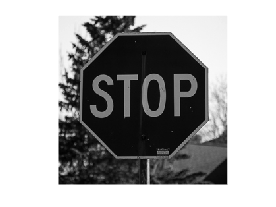

close all
clear

load stop_image

% Display original image

figure
imagesc(stop)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

## Case 1

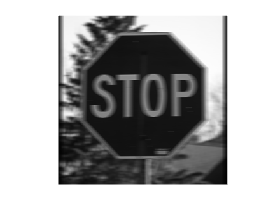

h = 0.1*ones(1,10); %<- Uncomment and complete

stop_h = conv2(stop,h);

figure
imagesc(stop_h)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

**Insert Notes Here (For Personal Reference Only): **

## Case 2

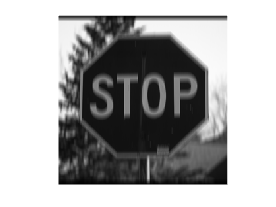

g = 0.1*ones(10,1); %<- Uncomment and complete

stop_g = conv2(stop,g);

figure
imagesc(stop_g)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

## Case 3

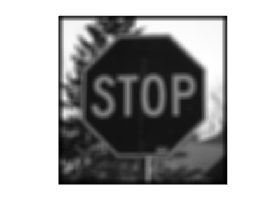

q = 0.01*ones(10,10); %<- Uncomment and complete

stop_q = conv2(stop,q);

figure
imagesc(stop_q)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

## Case 4

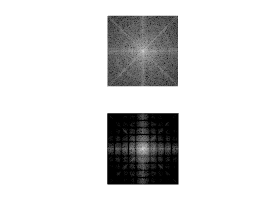

Stop = fft2(stop);

Stop_q = fft2(stop_q);

% Force same visual dynamic range on both images to avoid deception of
% autoscaling  Clim specifies min (black) and max (white) values of the
% display
Clim = [min(min(log10(abs(Stop)))), max(max(log10(abs(Stop))))];

figure
subplot(2,1,1)
imagesc(log10(abs(fftshift(Stop))),Clim)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

subplot(2,1,2)
imagesc(log10(abs(fftshift(Stop_q))),Clim)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

## Case 5

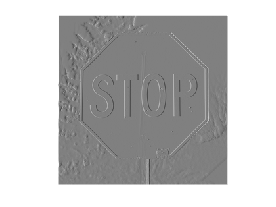

dh = [1 -1]; %<- Uncomment and complete

stop_dh = conv2(stop, dh);

figure
imagesc(stop_dh)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

## Case 6

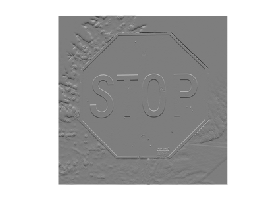

dv = [1 ; -1]; %<- Uncomment and complete

stop_dv = conv2(stop, dv);

figure
imagesc(stop_dv)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';

## Case 7

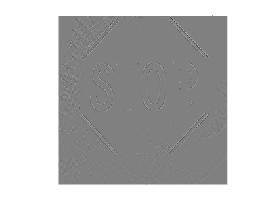

dvh = [1 -1; -1 1]; %<- Uncomment and complete

stop_dvh = conv2(stop, dvh);

figure
imagesc(stop_dvh)
axis square
colormap(gray)
ax = gca;
ax.Visible = 'off';